mm01 = load('01mm.dat');
mm11 = load('11mm.dat');
mm21 = load('21mm.dat');
mm31 = load('31mm.dat');
mm41 = load('41mm.dat');
mm51 = load('51mm.dat');
mm61 = load('61mm.dat');
mm71 = load('71mm.dat');

dx = 0.25; 
x = mm01(:, 1)' * 0.25;

p01 = polyval(c, mm01(:, 2));
p11 = polyval(c, mm11(:, 2));
p21 = polyval(c, mm21(:, 2));
p31 = polyval(c, mm31(:, 2));
p41 = polyval(c, mm41(:, 2));
p51 = polyval(c, mm51(:, 2));
p61 = polyval(c, mm61(:, 2));
p71 = polyval(c, mm71(:, 2));

pressure = [p01, p11, p21, p31, p41, p51, p61, p71];
zNames = {'1 мм'; '11 мм'; '21 мм'; '31 мм'; '41 мм'; '51 мм'; '61 мм'; '71 мм'}

zNames = 8×1 cell array
    {'1 мм' }
    {'11 мм'}
    {'21 мм'}
    {'31 мм'}
    {'41 мм'}
    {'51 мм'}
    {'61 мм'}
    {'71 мм'}


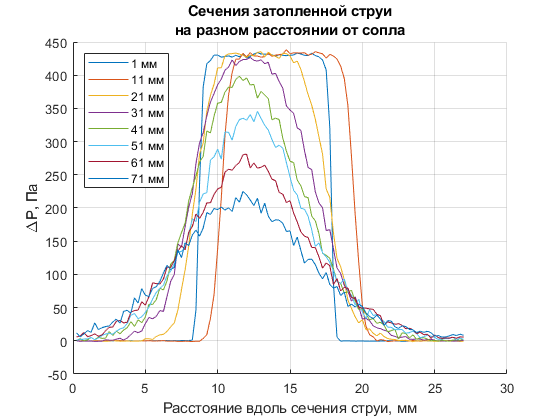

z = [1, 11, 21, 31, 41, 51, 61, 71];

f2 = figure();
hold on;
grid on;
title({'Сечения затопленной струи', 'на разном расстоянии от сопла'});
ylabel('\DeltaP, Па');
xlabel('Расстояние вдоль сечения струи, мм');

for i = 1:size(pressure, 2)
    plot(x, pressure(:, i), 'DisplayName', zNames{i});
end

legend('Location', 'NorthWest');

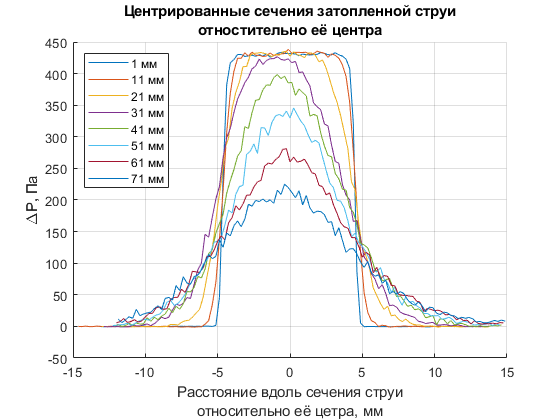








f3 = figure();
hold on;
grid on;
title({'Центрированные сечения затопленной струи', 'отностительно её центра'});
ylabel('\DeltaP, Па');
xlabel({'Расстояние вдоль сечения струи', 'относительно её цетра, мм'});

xCentered = zeros(size(pressure));
offset = 50;

for i = 1:size(pressure, 2)
    right = x(find(pressure(:, i) > offset, 1, 'last'));
    left = x(find(pressure(:, i) > offset, 1));
    
    center = left + (right - left) / 2;
    xCentered(:, i) = x - center;
    
    plot(xCentered(:, i), pressure(:, i), 'DisplayName', zNames{i});
end

legend('LOcation', 'NorthWest');